# Valors singulasrs SVD

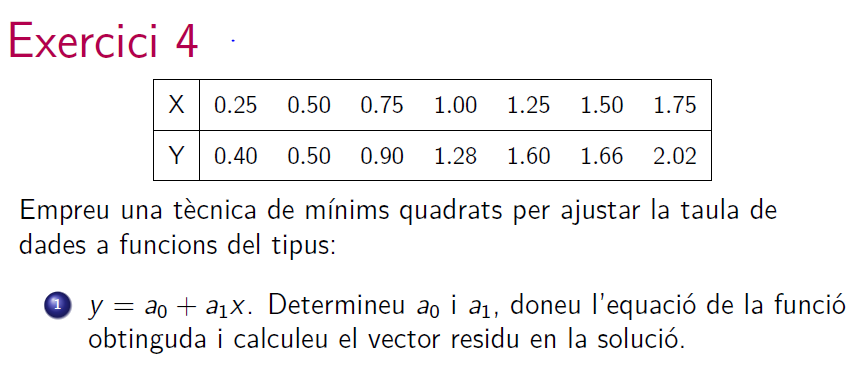

x = 0.25:0.25:1.75;
y = [4 5 9 12.8 16 16.6 20.2]/10;
plot(x,y,'*')
% Sistema lineal d'equacions associat al problema
A = [x', ones(size(x))']
b = y'
rank(A), rank([A,b])
% Equacions normals
sol = (A'*A)\(A'*b)
residu = norm(b-A*sol)

% SVD
[V,S,U] = svd(A)
sol2 = pinv(A)*b
u = 0:0.1:2;
v = polyval(sol, u);
plot(x, y, '*b', u ,v ,'r')

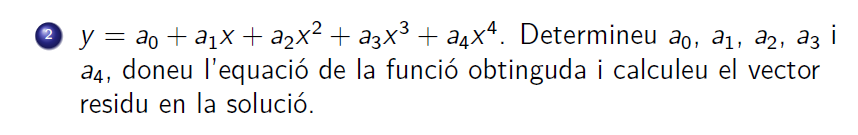

x = 0.25:0.25:1.75;
y = [4 5 9 12.8 16 16.6 20.2]/10;
plot(x,y,'*')
% Sistema lineal d'equacions associat al problema
A = [x.^4', x.^3', x.^2', x', ones(size(x))']
b = y'
rank(A), rank([A,b])
% Equacions normals
sol = (A'*A)\(A'*b)
residu = norm(b-A*sol)

% SVD
[V,S,U] = svd(A)
sol2 = pinv(A)*b
u = 0:0.1:2;
v = polyval(sol, u);
plot(x, y, '*b', u ,v ,'r')